#### IEEE 802.16d

IEEE802.16d属于对数正态阴影路径损耗模型，根据障碍物密度分为A,B,C型，模型表示为：


$$PL_{802.16}(d)[dB]=PL_F(d_0)+10\gamma log_{10}(d/d_0)+C_f+C_{Rx},d>d_0$$


其中$d_0=100m$，$\gamma = a-bh_{Tx}+c/h_{Rx}$,$C_f$与载波频率相关：$C_f=6log_{10}(f_c/2000)$，$C_{Rx}$与接收天线高度有关

#### 信道模型修正

由于原式在d=100处出现不间断点，对该模型修正后为：


$$PL_{M802.16}(d)[dB]=\left\{
20log_{10}(4\pi d/\lambda),d\leq d_0  \\ 20log_{10}(4\pi d_0/\lambda) + 10\gamma log_{10}(d/d_0)+C_f+C_Rx,d> d_0

$$


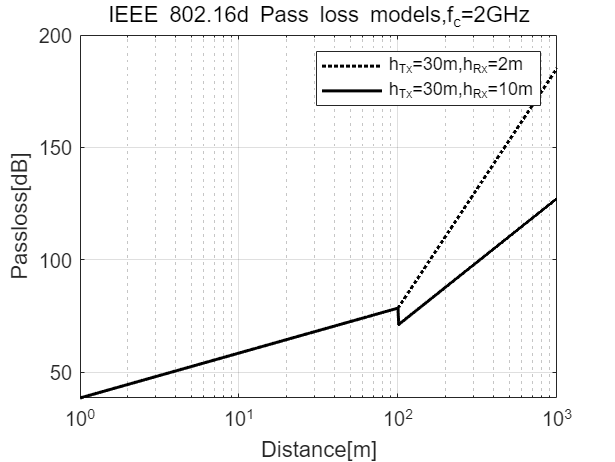

clear all;
clc;
fc = 2e9;
htx = [30 30];
hrx = [2 10];
distance = [1:1000];
for k=1:2
    y_IEEE16d(k,:) = PL_IEEE80216d(fc,distance,'A',htx(k),hrx(k),'atnt');
    y_MIEEE16d(k,:)= PL_IEEE80216d(fc,distance,'A',htx(k),hrx(k),'atnt','mod');
end

figure()
semilogx(distance,y_IEEE16d(1,:), 'k:','LineWidth',1.5);
hold on
semilogx(distance,y_IEEE16d(2,:),'k-','LineWidth',1.5);
grid on;
title(['IEEE 802.16d Pass loss models,f_c=',num2str(fc/1e9),'GHz'])
xlabel('Distance[m]')
ylabel('Passloss[dB]')
legend('h_{Tx}=30m,h_{Rx}=2m','h_{Tx}=30m,h_{Rx}=10m')

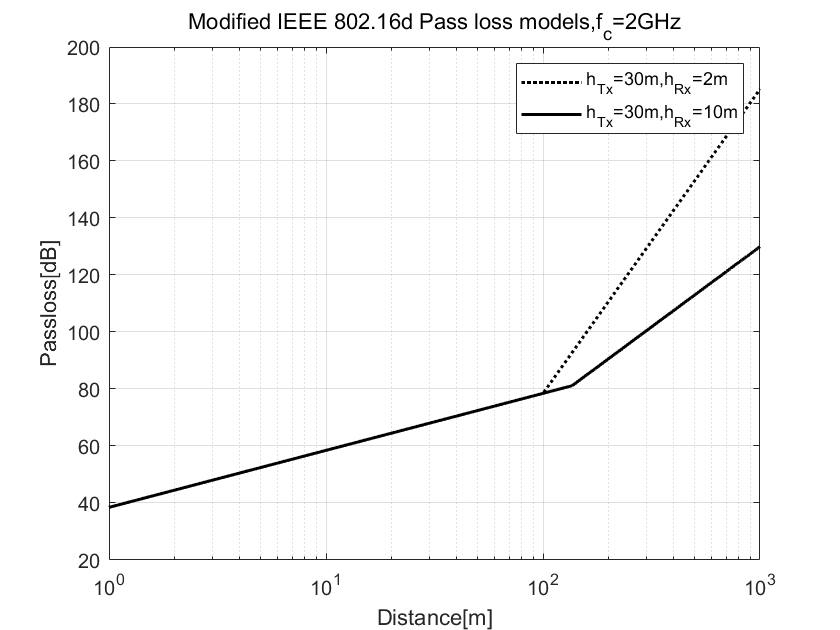


figure()
semilogx(distance,y_MIEEE16d(1,:), 'k:','LineWidth',1.5);
hold on
semilogx(distance,y_MIEEE16d(2,:),'k-','LineWidth',1.5);
grid on;
title(['Modified IEEE 802.16d Pass loss models,f_c=',num2str(fc/1e9),'GHz'])
xlabel('Distance[m]')
ylabel('Passloss[dB]')
legend('h_{Tx}=30m,h_{Rx}=2m','h_{Tx}=30m,h_{Rx}=10m')

function PL = PL_IEEE80216d(fc,d,type,htx,hrx,corr_fact,mod)
%IEEE 802.16d模型
%输入：
%       fc      ：   载波频率
%       d       :   基站和移动台之间的距离
%       type    :   三种类型，'A','B','C'
%       htx     :   发射机高度
%       hrx     :   接收机高度
%       corr_fact:  如果存在阴影，设置为'ATnT'或'Okumura'，否则为'NO'
%       mod     :   设置'mod'得到修正后的IEEE 802.16d模型
if nargin>6
       Mod = upper(mod);
else
    Mod = 'UNMOD';
end
if nargin==6 && corr_fact(1)=='m'
    Mod = 'MOD';
    corr_fact = 'NO';
elseif( nargin <6 )
    corr_fact = 'NO';
    if nargin==5 && hrx(1)=='m'
        Mod = 'MOD';
        hrx=2;
    elseif nargin < 5
        hrx=2;
        if(nargin==4 && htx(1)=='m')
            Mod='MOD';
            htx=30;
        elseif nargin<4
            htx = 30;
            if(nargin==3 && type(1)=='m')
                Mod = 'MOD';
                type = 'A';
            elseif nargin <3
                type='A';
            end
        end
    end
end
d0=100;
Type = upper(type);
if Type~='A' && Type~='B' && Type~='C'
    disp('Error:The selected type is not supported');
    return;
end
switch upper(corr_fact)
    case 'ATNT'
        PLf = 6*log10(fc/2e9);
        PLh = -10.8*log10(hrx/2);
    case 'OKUMURA'
        PLf = 6*log10(fc/2e9);
        if hrx <=3
            C_Rx = -10*log10(hrx/3);
        else 
            C_Rx = -20*log10(hrx/3);
        end
    case 'NO'
        PLf=0;
        PLh=0;
end

if Type=='A'
    a = 4.6;
    b = 0.0075;
    c = 12.6;
elseif Type == 'B'
    a =4;
    b = 0.0065;
    c = 17.1;
else 
    a =3.6;
    b = 0.005;
    c = 20;
end

lambda = physconst('l')/fc;
gamma = a-b*htx + c/hrx;
d0_pr = d0;
if Mod(1)=='M'
    d0_pr = d0*10^-((PLf+PLh)/(10*gamma));
end
A = 20*log10(4*pi*d0_pr/lambda)+PLf+PLh;
for k = 1:length(d)
    if(d(k)>d0_pr)
        PL(k) = A+10*gamma*log10(d(k)/d0);
    else
        PL(k) = -10*log10((lambda/(4*pi*d(k)))^2);
    end
end
end